clc
clear

recobj = audiorecorder;
disp('Start speking');

Start speking


recordblocking(recobj,5);
disp('End of Recording');

End of Recording


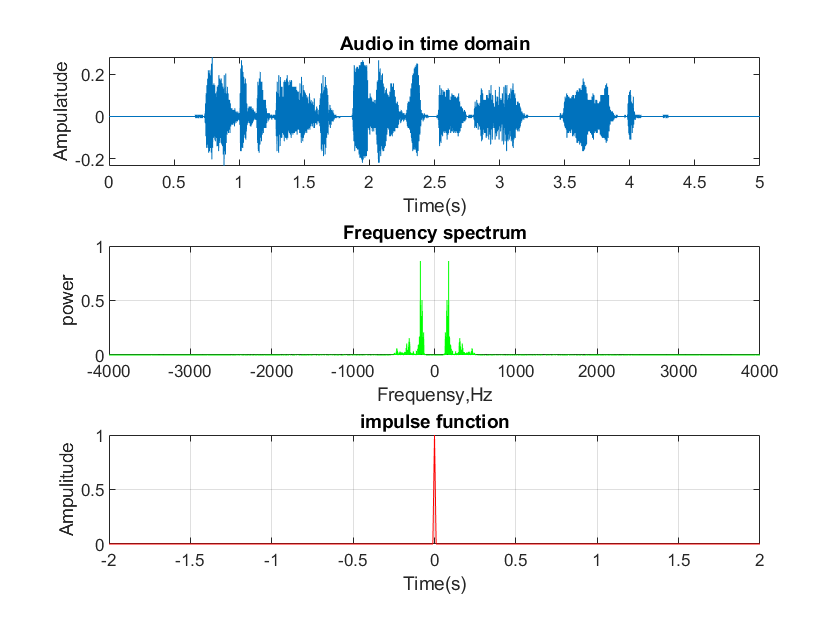


%%play(recobj);

myRecording=getaudiodata(recobj);

subplot(3,1,1)
m=length(myRecording);
t=0:5/m:5-5/m;

plot(t,myRecording);
xlabel('Time(s)');
ylabel('Ampulatude');
title ("Audio in time domain");
%%disp(recobj);

y=fftshift(fft(myRecording));
fs=8000;
n=length(y);
f=(-n/2:n/2-1)*(fs/n);
subplot(3,1,2)
po=abs(y).^2/n;
plot(f,po,'g');
xlabel('Frequensy,Hz');
ylabel('power');
title('Frequency spectrum');
grid on;

t1=(-2:0.01:2);
impulse=t1==0;
unitstep=t1>=0;

subplot(3,1,3)
plot(t1,impulse,'r');
xlabel('Time(s)');
ylabel('Ampulitude');
title('impulse function');
grid on;

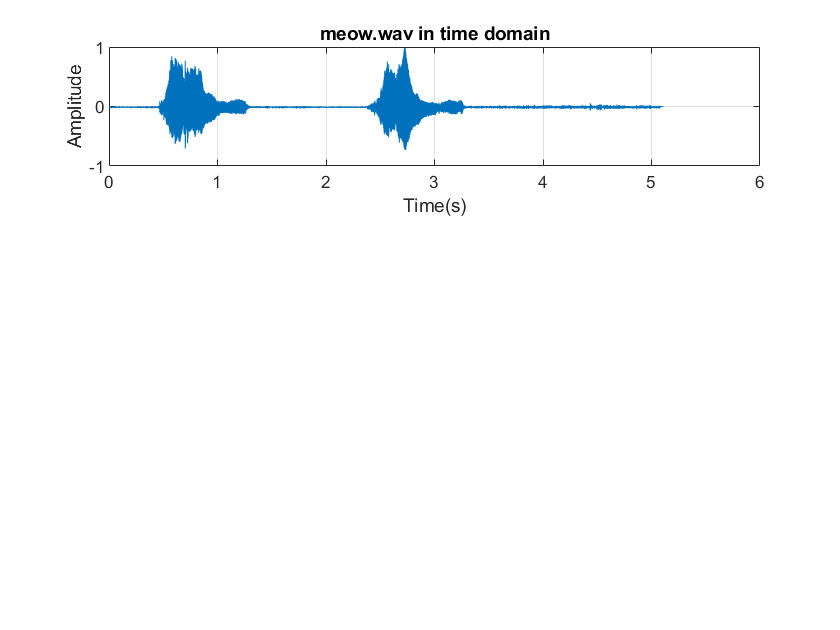


%%%%


figure
%plot the audio signal
[y,Fs]=audioread('meow.wav');

y=y(:,1);
dt2=1/Fs;
t2=0:dt2 :(length(y)*dt2)-dt2;

subplot(3,1,1);
plot(t2,y); 
xlabel('Time(s)');
ylabel('Amplitude');
title('meow.wav in time domain')
grid on;

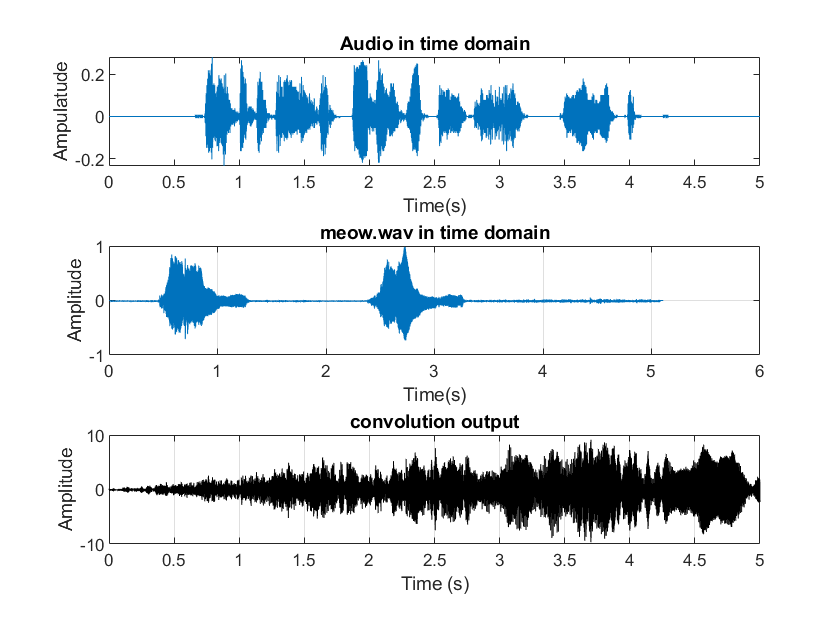


%convolution
figure
subplot(3,1,1)
m=length(myRecording);
t=0:5/m:5-5/m;

plot(t,myRecording);
xlabel('Time(s)');
ylabel('Ampulatude');
title ("Audio in time domain");

subplot(3,1,2);
plot(t2,y); 
xlabel('Time(s)');
ylabel('Amplitude');
title('meow.wav in time domain')
grid on;


n=10;
delayed_signal=[zeros(n,1);myRecording];
out = conv(myRecording,y,'same');


subplot(3,1,3)
plot(t,out,'k');
xlabel('Time (s)');
ylabel('Amplitude');
title('convolution output');
grid on;

%%sound(out,8000);

